## 1. The Experiment

The data in this project was collected using an experimental design based on [Warren et al.'s 2016](https://doi.org/10.1109/JPROC.2015.2507180) study. In that study, a participant underwent the implantation of Utah Slanted Electrode Arrays in both the ulnar and median nerves of their remaining limb after an amputation procedure. Subsequently, the participant engaged with a virtual hand displayed on a screen, which repeatedly executed two distinct gestures. The primary task of the participant was to "replicate" the motions of this virtual hand using the remaining muscles in their amputated limb. Throughout this process, the USEAs recorded neural signals from the nerves while a computer program tracked the hand's kinematics (i.e., the change of the virtual joint positions over time). The researchers' goal was to decode joint kinematics from the neural signals. [Link to video of the task](https://youtu.be/6V8tcX5m3PQ)

## 2. The Dataset

clearvars
load('datasets\training_dataset.mat')
experiment_data = training_data;

The variable `experiment_data` is a [MATLAB struct](https://www.mathworks.com/help/matlab/ref/struct.html) that contains two matrices and one variable:

- `experiment_data.hand_kinematics`.- An Nx2 matrix containing the kinematic information of **two joints **of the virtual hand during the experiment.

- `experiment_data.raw_neural_data`: An Nx6 matrix containing a **subset of six USEA channels** during the experiment.

- `experiment_data.sample_rate`.- The sample rate in Hz at which both Kinematics and Neural Data were recorded.

The following code will help you visualize and understand the dataset. 

experiment_ttbl = struct_to_timetable(experiment_data)

experiment_ttbl = 948199×2 timetable
         Time         Hand Kinematics    Raw Neural Data
    ______________    _______________    _______________

    0 sec                 0    0           1×6 single   
    3.3333e-05 sec        0    0           1×6 single   
    6.6667e-05 sec        0    0           1×6 single   
    0.0001 sec            0    0           1×6 single   
    0.00013333 sec        0    0           1×6 single   
    0.00016667 sec        0    0           1×6 single   
    0.0002 sec            0    0           1×6 single   
    0.00023333 sec        0    0           1×6 single   
    0.00026667 sec        0    0           1×6 single   
    0.0003 sec            0    0           1×6 single   
    <s

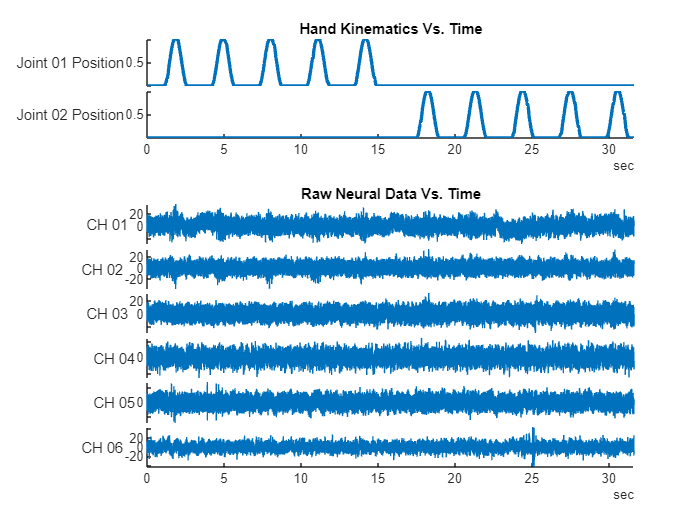

experiment_fig = plot_timetable(experiment_ttbl);

## 3. The Research Objective

One of the goals of this project is for you to train a Neural Network to map the values of the USEA data to the values of the hand kinematics. In other words, you will train an algorithm to decode the desired position of an artificial hand based on the current electrical activity in the patient's remaining limb. However, in their current state, the neural signals have almost no correlation to the hand kinematics, and the neural network won't be able to learn this mapping. Therefore, you will have to explore ways to extract features from these signals that correlate better with the kinematics.

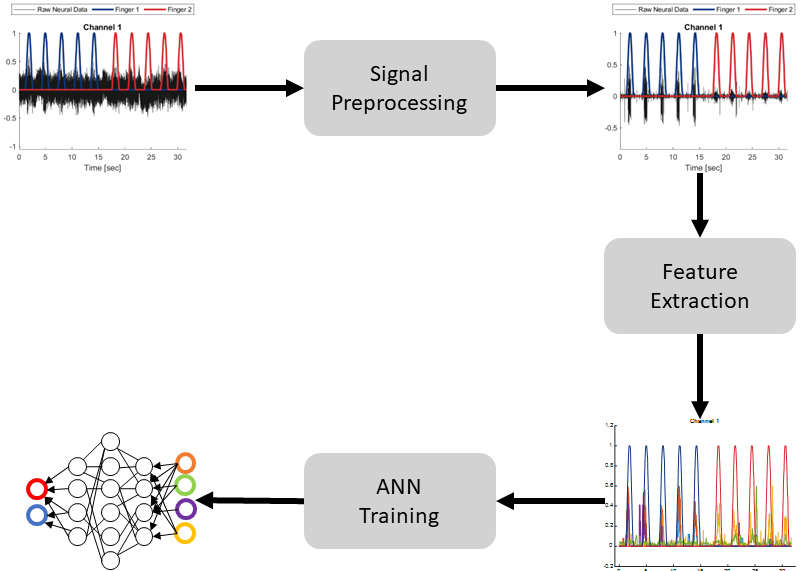

## Helper Functions

function ttbl = struct_to_timetable(experiment_data)
ttbl = timetable( experiment_data.hand_kinematics, experiment_data.raw_neural_data, ...
    'SampleRate', experiment_data.sample_rate, ...
    'VariableNames', ["Hand Kinematics" "Raw Neural Data"]);
end

function tlo = plot_timetable(experiment_ttbl)
tlo = tiledlayout(3,1);
nexttile
stackedplot(experiment_ttbl.Time, experiment_ttbl{:,"Hand Kinematics"}, 'LineWidth', 2, ...
    "Title", "Hand Kinematics Vs. Time", ...
    "DisplayLabels", ["Joint 01 Position", "Joint 02 Position"])
nexttile([2,1])
stackedplot(experiment_ttbl.Time, experiment_ttbl{:,"Raw Neural Data"}, ...
    "Title", "Raw Neural Data Vs. Time", ...
    "DisplayLabels", ["CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"])
end